clear
close all
targetImage = im2double(imread("dogdogorange.png"));

imagefiles = dir("data64\cat\*.jpg");
filepath = "data64\cat"

filepath = "data64\cat"


rTileSize = 64;
oTileSize = 16;
tileRatio = oTileSize/rTileSize*2;
nrOfPrimaryColours = 3;

[rows, cols, ~] = size(targetImage)

rows = 867

cols = 701

tileRows = ceil(rows / oTileSize)

tileRows = 55

tileCols = ceil(cols / oTileSize)

tileCols = 44


outputImage = zeros(tileRows*rTileSize*tileRatio, tileCols*rTileSize*tileRatio,3);

processbar = waitbar(0, 'Loading Images...');
numberOfImages = 1000%15165

numberOfImages = 1000

for ii=1:numberOfImages
    waitbar(ii/numberOfImages, processbar, "Loading Images...");
    currentfilename = imagefiles(ii).name;
    currentimage = im2double(imread(filepath + "\" +  currentfilename));
    images{ii, 1} = currentimage;
    images{ii, 2} = getImportantColours(currentimage, nrOfPrimaryColours);
end
close(processbar)

processbar = waitbar(0, 'Load Colours...');
for c = 1:tileCols 
    waitbar(c/tileCols, processbar, "Load Colours...");
    for r = 1:tileRows       
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);
        wantedTiles{r,c} = currentTile;
        targetPrimaryColours = getImportantColours(currentTile, nrOfPrimaryColours);
        [~, cMax] = size(targetPrimaryColours);
        for colour = 1:cMax
            targetColours{r, c, colour} = targetPrimaryColours(:,colour);
        end
    end
end
close(processbar)

processedImages = preprocessImages3(images, targetColours, 1, tileRatio, nrOfPrimaryColours);

ans =      0     1     2     3     5     6     7     8     9    10    11    13    14    15    16    17    18    19    20    22    23    24    25    26    27    28    29    31    32    33    34    35    36    37    38    39    40    42    43    44    45    46    47    48    49    50    51    53    54    55


[datasetSize, ~] = size(processedImages)

datasetSize = 787

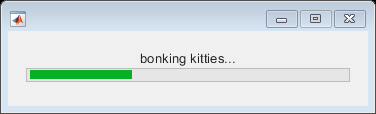

Index in position 1 is invalid. Array indices must be positive integers or logical values.

processbar = waitbar(0, 'Processing Images...');
addedImages = [];
tic
% go through each tile
for c = 1:1:tileCols
    waitbar(c/tileCols, processbar, "bonking kitties...");
    for r = 1:1:tileRows       
        tileRFrom = 1 + (r-1)*(rTileSize * tileRatio);
        tileRTo = r*rTileSize* tileRatio;
        tileCFrom = 1 + (c-1)*(rTileSize* tileRatio);
        tileCTo = c*rTileSize* tileRatio;

        currentTile = wantedTiles{r,c};
        
        for colour = 1:(nrOfPrimaryColours)
            colours = targetColours{r,c,colour};
            targetPrimaryColours(:, colour) = colours;
        end

        lowerDeltaEImages = {}; %holds index value to processed images        
        bestImageIndex = 0;
        bestDelta = 9999;
        imageFound = false;
        % find best image for each tile
        for i = 1:datasetSize     
            curImg = processedImages{i,1};
            currentPrimaryColours = processColours;

            if comparePrimaryColours(targetPrimaryColours, currentPrimaryColours, 0.5)
                bestImageIndex = i;
                lowerDeltaEImages{end+1} = i;
                imageFound = true;
            end

            
            %curImg = processedImages{i,1};
            %currentPrimaryColours = processColours;
            %currentDelta = comparePrimaryColours2(targetPrimaryColours, currentPrimaryColours);
            %if currentDelta < bestDelta
            %    bestImageIndex = i;
            %    bestDelta = currentDelta;
            %end
        end
        %Subsampling
        subsamplesAmt = 9;      
        subsampledTargetTile = subsampleImage(currentTile, subsamplesAmt);
        
        % till loop för att checka L skillnad i 3x3
        smallestMSE = 9999;
        %length(lowerDeltaEImages)
        for q = 1:length(lowerDeltaEImages)
            subsampledCurrentImage = subsampleImage(processedImages{lowerDeltaEImages{q}}, subsamplesAmt);
            MSE = subsampledCmp(subsampledTargetTile, subsampledCurrentImage, subsamplesAmt);
            if(MSE < smallestMSE)
                smallestMSE = MSE;
                bestImageIndex = lowerDeltaEImages{q};
            end
        end
        % if we have not found a cat add the best cat
        if isempty(lowerDeltaEImages)
            bestDelta = 9999;
            
            for i = 1:datasetSize
                curImg = processedImages{i,1};
                currentPrimaryColours = processColours;
                currentDelta = comparePrimaryColours2(targetPrimaryColours, currentPrimaryColours);
                if currentDelta < bestDelta
                    bestImageIndex = i;
                    bestDelta = currentDelta;
                end
            end
        end
        
        
        imageToAdd = processedImages{bestImageIndex,1};
        outputImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :) = imageToAdd;
    end   
end

toc
close(processbar)

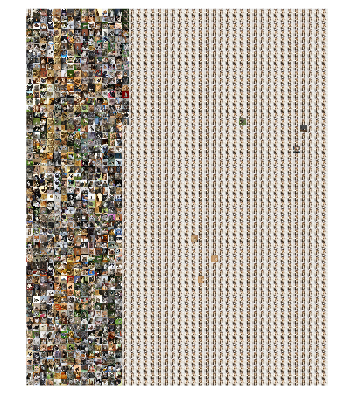

imshow(outputImage)

outputImage

outputImage = outputImage(:,:,1) =

    0.8532    0.8735    0.8855    0.8932    0.8915    0.9258    0.8138    0.6262    0.6987    0.7004    0.7263    0.8593    0.9558    0.9681    0.9009    0.7168    0.7584    0.6765    0.4050    0.5013    0.5335    0.5834    0.8157    0.8932    0.9086    0.9118    0.9090    0.9030    0.8961    0.8848    0.8916    0.8843    0.2876    0.3271    0.3190    0.3348    0.4306    0.6629    0.8569    0.8714    0.8735    0.8565    0.8369    0.8222    0.8112    0.8054    0.7884    0.7510    0.6997    0.6662    0.5516    0.3867    0.1389    0.0467    0.1049    0.0793    0.1545    0.2539    0.1760    0.1504    0.1429    0.1230    0.1160    0.1023    0.6947    0.7345    0.7484    0.7534    0.7466    0.5539    0.3119    0.2808    0.2809    0.2620    0.2502    0.2439    0.2375    0.2334    0.2228    0.2051    0.1932    0.1671    0.1329    0.1436    0.2224    0.3087    0.3748    0.4188    0.4435    0.4943    0.3687    0.2167    0.4432    0.5076    0.4704    0.4664    